## Définition des variables

Dans cette section nous allons définir les variables qui vons nous être utiles pour la modélisation. 

### Variables pour les degrées de libertés (DDL)

Le tableau suivant utilise la notation définie par SNAME(1950).

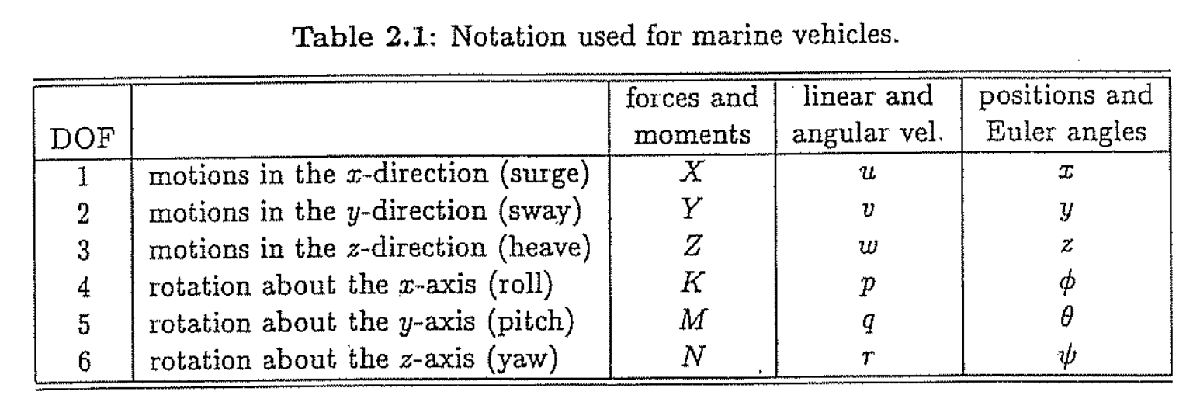

Étant donné que nous voulons utiliser les quaternions, nous n'allons pas définir les angles d'Euler

clear;
sympref('MatrixWithSquareBrackets',true)

ans = logical
   1


    
% Définir les forces et moments
    syms X Y Z K M N
    syms Fm
    syms tauE
    
% Définir les vitesses linéaires et angulaires
    syms u v w p q r

% Définir les positions linéaires
    syms x y z
    
% Définir les entrées système (Thruster)
    syms ('U',[8,1])

### Variables pour le quaternion

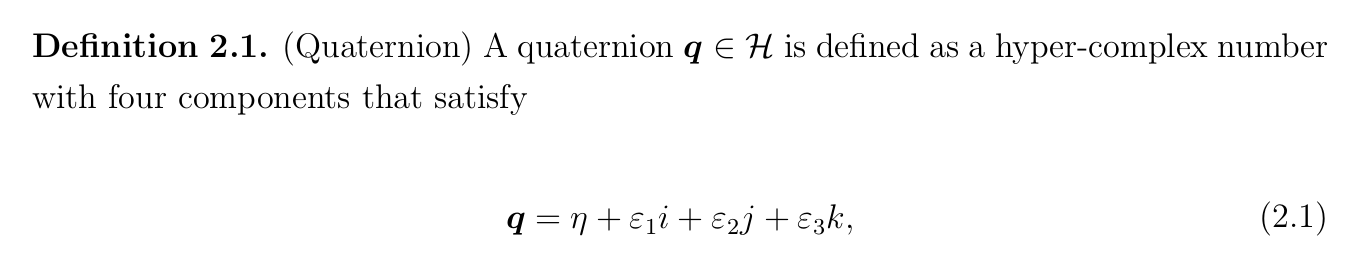

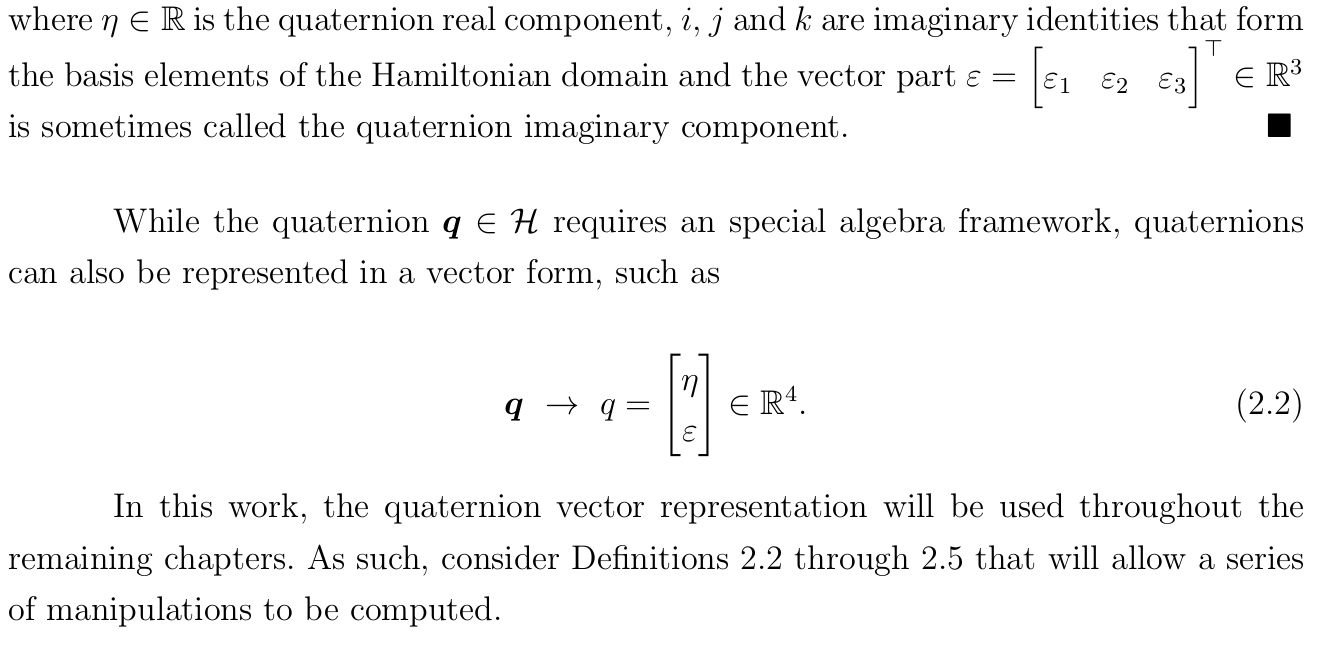

    % Définir la partie scalaire
        syms eta;
        
    % Définir la partie vectorielle
        syms('epsilon',[3,1]);
    
    % Définir le quaternion  
        e=[eta; epsilon];

### Constante du modèle physique

% distance truster x y z selon centre geommétrique (Constantes)
% D14 distance thruster 1 a 4. (Constantes)
% D58 distance thruster 5 a 8. (Constantes)
% a14 angle thruster 1 a 4. (Constantes)
% dz distance entre les increments sur le frame. (Constantes)
% PZ position des truster sur le frame. (Constantes)
    syms('D14',[1 3]); syms('D58',[1 3]) ; syms a14 dz ; syms ('PZ',[1,4]);

% masse, volume du prototype et hauteur sub (Constantes)
    syms mass volume height

% coefficient de drag (Constantes)
    syms ('CD_L',[1, 6])    % Lineaire
    syms ('CD_Q', [1, 6]);  % Quadratique

% aire de surface du sub (Constantes)
    syms ('AF', [1, 3]);

% matrice d'inertie (Constantes)
    syms ('I', [3, 3]);

% centre de gravité RG et centre de flotataison RB (Constantes)
    syms ('RG',[3 1]); syms('RB',[3 1])
    
% Constantes physique (densité de leau et accélération gravitationel)
    syms rho g


### Regroupement des variables

Nous allons par la suite regrouper les variables

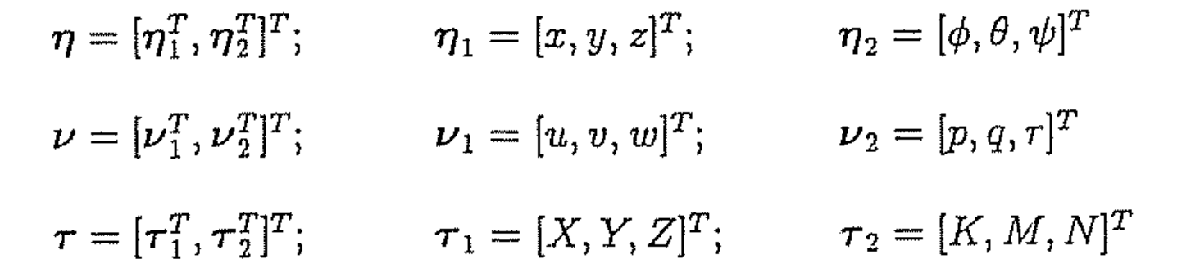

% Position et Orientation 
    n1= [x,y,z].';
    Ne=[n1;e]

$$Ne = \left[\begin{array}{c} x\\ y\\ z\\ \eta \\ \epsilon_{1}\\ \epsilon_{2}\\ \epsilon_{3} \end{array}\right]$$

    
% Vitesses
    v1=[u,v,w].';
    v2=[p,q,r].';
    V=[v1;v2]

$$V = \left[\begin{array}{c} u\\ v\\ w\\ p\\ q\\ r \end{array}\right]$$

    
% Forces et moments
   Fm=[X,Y,Z,K,M,N].';
   
% Constance Mecanique
   constMec = [D14 D58 a14 dz PZ mass volume height AF...
             I(1,:) I(2,:) I(3,:) RG.' RB.' CD_L CD_Q rho g];
         

## Équation cinématique du mouvement

### Transformation de la vitesse linéaire

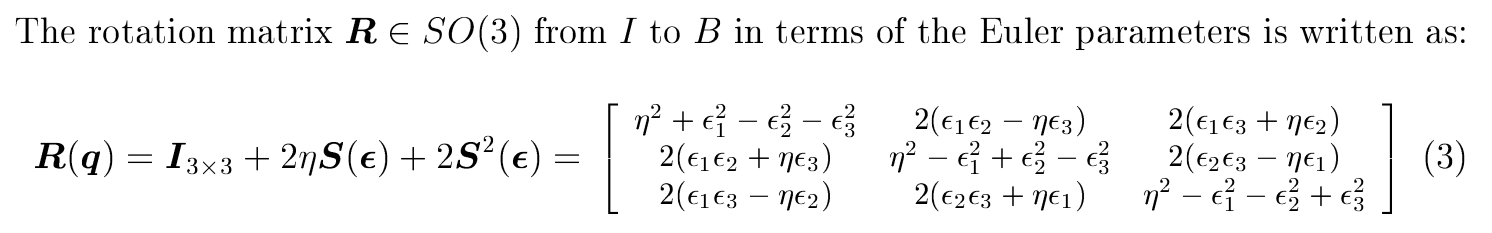

    % Équation 3
    E1=eye(3)+2*eta*skew(epsilon)+2*skew(epsilon)^2

$$E1 = \left[\begin{array}{ccc} -2\,{\epsilon_{2}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{2}}^{2}+1 \end{array}\right]$$

    E1.'

$$ans = \left[\begin{array}{ccc} -2\,{\epsilon_{2}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{2}}^{2}+1 \end{array}\right]$$

    simplify(inv(E1))

    % Équation 2.24 (Fossen)
    EE1=[(eta^2-epsilon.'*epsilon)*eye(3)+2*epsilon*epsilon.'-2*eta*skew(epsilon)].'

$$EE1 = \left[\begin{array}{ccc} {\epsilon_{1}}^{2}-{\epsilon_{2}}^{2}-{\epsilon_{3}}^{2}+\eta^{2} & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -{\epsilon_{1}}^{2}+{\epsilon_{2}}^{2}-{\epsilon_{3}}^{2}+\eta^{2} & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -{\epsilon_{1}}^{2}-{\epsilon_{2}}^{2}+{\epsilon_{3}}^{2}+\eta^{2} \end{array}\right]$$

### Transformation de la vitesse angulaire

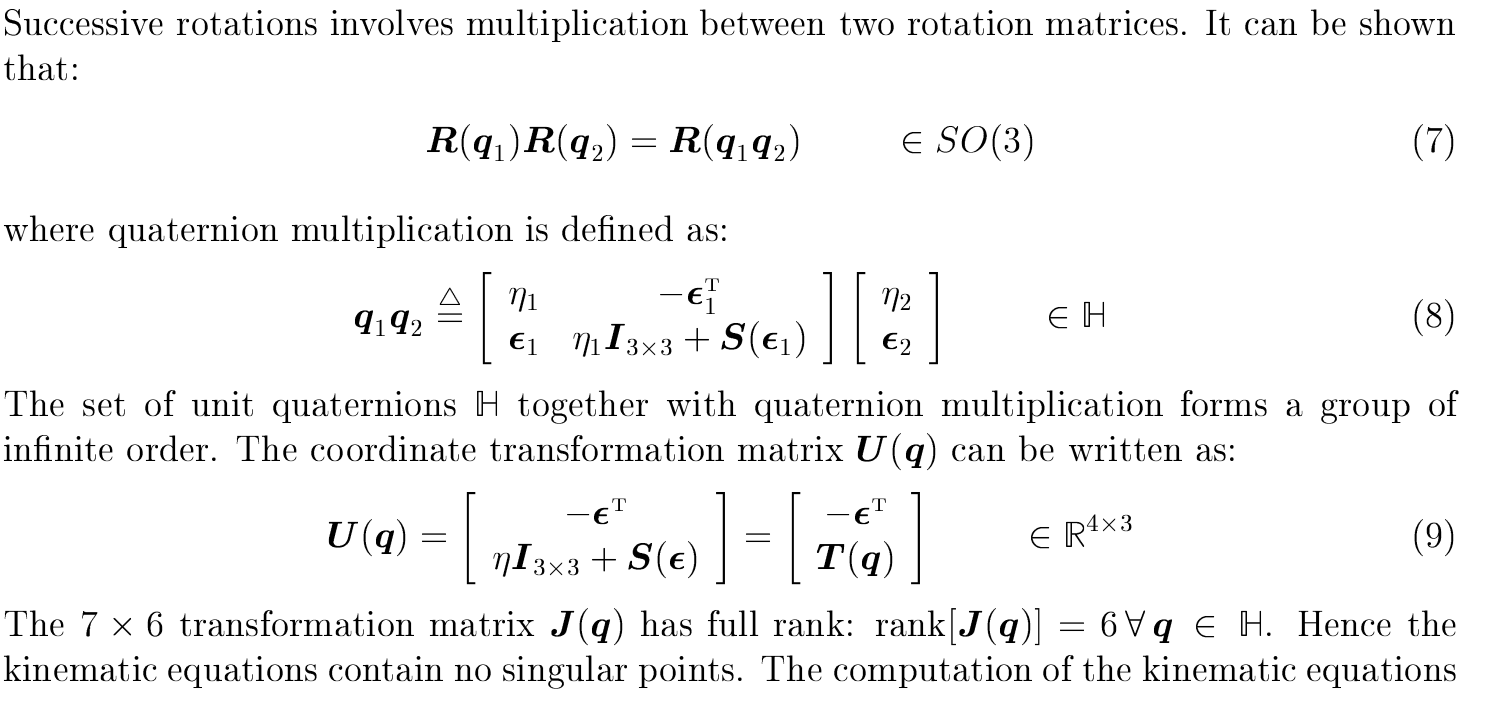

   E2=[-epsilon.';eta*eye(3)+skew(epsilon)]

$$E2 = \left[\begin{array}{ccc} -\epsilon_{1} & -\epsilon_{2} & -\epsilon_{3}\\ \eta & -\epsilon_{3} & \epsilon_{2}\\ \epsilon_{3} & \eta & -\epsilon_{1}\\ -\epsilon_{2} & \epsilon_{1} & \eta \end{array}\right]$$

### Matrice de transformation

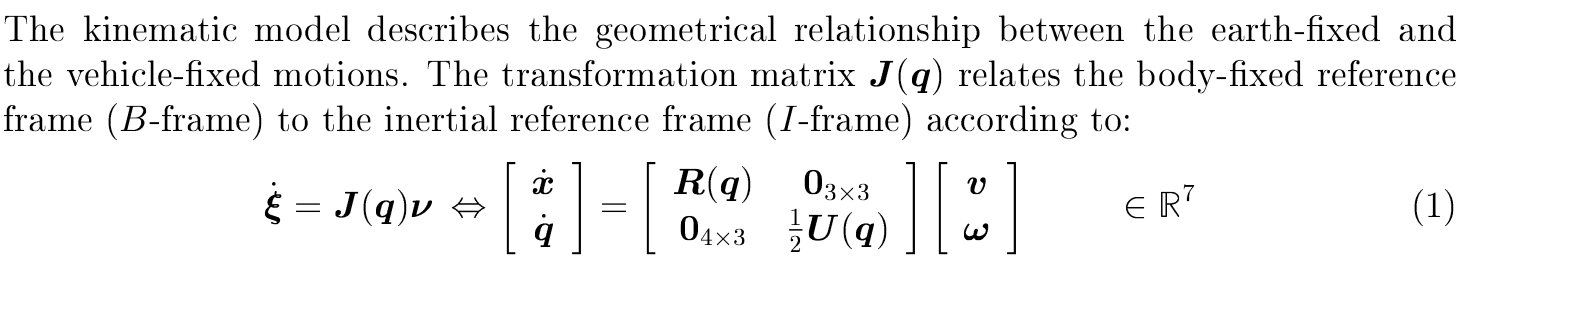

% Définir la matrice de transformation J(q)
   J=[EE1,zeros(3,3);
   zeros(4,3),(1/2)*E2]

$$J = \left[\begin{array}{cccccc} {\epsilon_{1}}^{2}-{\epsilon_{2}}^{2}-{\epsilon_{3}}^{2}+\eta^{2} & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta & 0 & 0 & 0\\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -{\epsilon_{1}}^{2}+{\epsilon_{2}}^{2}-{\epsilon_{3}}^{2}+\eta^{2} & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta & 0 & 0 & 0\\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -{\epsilon_{1}}^{2}-{\epsilon_{2}}^{2}+{\epsilon_{3}}^{2}+\eta^{2} & 0 & 0 & 0\\ 0 & 0 & 0 & -\frac{\epsilon_{1}}{2} & -\frac{\epsilon_{2}}{2} & -\frac{\epsilon_{3}}{2}\\ 0 & 0 & 0 & \frac{\eta }{2} & -\frac{\epsilon_{3}}{2} & \frac{\epsilon_{2}}{2}\\ 0 & 0 & 0 & \frac{\epsilon_{3}}{2} & \frac{\eta }{2} & -\frac{\epsilon_{1}}{2}\\ 0 & 0 & 0 & -\frac{\epsilon_{2}}{2} & \frac{\epsilon_{1}}{2} & \frac{\eta }{2} \end{array}\right]$$

## Équation dynamique d'un corps rigide

### Matrice des masses et d'inertie

% Corp rigide
Mrb=[mass*eye(3),-mass*skew(RG);
     mass*skew(RG),I ]

$$Mrb = \left[\begin{array}{cccccc} \mathrm{mass} & 0 & 0 & 0 & {\mathrm{RG}}_{3}\,\mathrm{mass} & -{\mathrm{RG}}_{2}\,\mathrm{mass}\\ 0 & \mathrm{mass} & 0 & -{\mathrm{RG}}_{3}\,\mathrm{mass} & 0 & {\mathrm{RG}}_{1}\,\mathrm{mass}\\ 0 & 0 & \mathrm{mass} & {\mathrm{RG}}_{2}\,\mathrm{mass} & -{\mathrm{RG}}_{1}\,\mathrm{mass} & 0\\ 0 & -{\mathrm{RG}}_{3}\,\mathrm{mass} & {\mathrm{RG}}_{2}\,\mathrm{mass} & I_{1,1} & I_{1,2} & I_{1,3}\\ {\mathrm{RG}}_{3}\,\mathrm{mass} & 0 & -{\mathrm{RG}}_{1}\,\mathrm{mass} & I_{2,1} & I_{2,2} & I_{2,3}\\ -{\mathrm{RG}}_{2}\,\mathrm{mass} & {\mathrm{RG}}_{1}\,\mathrm{mass} & 0 & I_{3,1} & I_{3,2} & I_{3,3} \end{array}\right]$$

 
% Masse ajouté 
Ma1 = [zeros(3,3)];
Ma2 = [zeros(3,3)];
Ma3 = [zeros(3,3)];
Ma4 = [zeros(3,3)];

Ma = [Ma1,Ma2;
      Ma3,Ma4]

Ma =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


  
M = Mrb + Ma;

### Matrice de Coriolis

% Corp rigide
Crb= [zeros(3,3), -mass*skew(v1)- mass*skew(skew(v2)*RG);
     -mass*skew(v1)- mass*skew(skew(v2)*RG), skew(I*v2)+mass*skew(skew(v1)*RG)]

$$Crb = \begin{array}{l} \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v\\ 0 & 0 & 0 & -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4}\\ 0 & 0 & 0 & \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0\\ 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v & 0 & -I_{3,1}\,p-I_{3,2}\,q-I_{3,3}\,r-\sigma_{3} & I_{2,1}\,p+I_{2,2}\,q+I_{2,3}\,r-\sigma_{2}\\ -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4} & I_{3,1}\,p+I_{3,2}\,q+I_{3,3}\,r+\sigma_{3} & 0 & -I_{1,1}\,p-I_{1,2}\,q-I_{1,3}\,r-\sigma_{1}\\ \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0 & \sigma_{2}-I_{2,2}\,q-I_{2,3}\,r-I_{2,1}\,p & I_{1,1}\,p+I_{1,2}\,q+I_{1,3}\,r+\sigma_{1} & 0 \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,v-{\mathrm{RG}}_{2}\,w\right)\\ \sigma_{2}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,u-{\mathrm{RG}}_{1}\,w\right)\\ \sigma_{3}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,u-{\mathrm{RG}}_{1}\,v\right)\\ \sigma_{4}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,q-{\mathrm{RG}}_{2}\,r\right)\\ \sigma_{5}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,p-{\mathrm{RG}}_{1}\,r\right)\\ \sigma_{6}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,p-{\mathrm{RG}}_{1}\,q\right) \end{array}$$


% Masse ajouté
Ca =[zeros(3,3), -skew(Ma1*v1+Ma2*v2);
     -skew(Ma1*v1+Ma2*v2), -skew(Ma3*v1+Ma4*v2)]

$$Ca = \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

 
C = Crb + Ca

$$C = \begin{array}{l} \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v\\ 0 & 0 & 0 & -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4}\\ 0 & 0 & 0 & \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0\\ 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v & 0 & -I_{3,1}\,p-I_{3,2}\,q-I_{3,3}\,r-\sigma_{3} & I_{2,1}\,p+I_{2,2}\,q+I_{2,3}\,r-\sigma_{2}\\ -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4} & I_{3,1}\,p+I_{3,2}\,q+I_{3,3}\,r+\sigma_{3} & 0 & -I_{1,1}\,p-I_{1,2}\,q-I_{1,3}\,r-\sigma_{1}\\ \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0 & \sigma_{2}-I_{2,2}\,q-I_{2,3}\,r-I_{2,1}\,p & I_{1,1}\,p+I_{1,2}\,q+I_{1,3}\,r+\sigma_{1} & 0 \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,v-{\mathrm{RG}}_{2}\,w\right)\\ \sigma_{2}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,u-{\mathrm{RG}}_{1}\,w\right)\\ \sigma_{3}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,u-{\mathrm{RG}}_{1}\,v\right)\\ \sigma_{4}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,q-{\mathrm{RG}}_{2}\,r\right)\\ \sigma_{5}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,p-{\mathrm{RG}}_{1}\,r\right)\\ \sigma_{6}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,p-{\mathrm{RG}}_{1}\,q\right) \end{array}$$

### Matrice de damping

% Equation quadratique de damping
xu = ((1/2) * rho * CD_Q1 * AF1 * abs(u));
yv = ((1/2) * rho * CD_Q2 * AF2 * abs(v));
zw = ((1/2) * rho * CD_Q3 * AF3 * abs(w));
kp = ((1/2) * rho * CD_Q4 * AF3 * abs(p));
mq = ((1/2) * rho * CD_Q5 * AF3 * abs(q));
nr = ((1/2) * rho * CD_Q6 * AF2 * abs(r));

% Matrice quadratic damping.
Dq = diag([xu yv zw kp mq nr])

$$Dq = \left[\begin{array}{cccccc} \frac{{\mathrm{AF}}_{1}\,{\mathrm{CD}}_{\mathrm{Q1}}\,\rho \,\left|u\right|}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q2}}\,\rho \,\left|v\right|}{2} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q3}}\,\rho \,\left|w\right|}{2} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q4}}\,\rho \,\left|p\right|}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q5}}\,\rho \,\left|q\right|}{2} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q6}}\,\rho \,\left|r\right|}{2} \end{array}\right]$$


% Matrice linear damping.
Dl = diag(CD_L);

D = (Dl + Dq);

### Matrice de gravité 

% Matrice de gravité

% Équation du volume submergé selon la profondeur z.     /͞ ͞
% Équation à double asymptote horizontal. Voir erf()  __/

% Calculs des constantes
aa= volume/2;   % Calculer l'amplitude.
kk=aa;          % Monter la courbe pour avoir min 0 et max volume.
bb=4/height;    % Calculer la pente transitoire.
hh=height/2;    % Décaler la courbe pour avoir x(0)=0. 

% Équation
vz=aa*erf(bb*(z-hh))+kk;

% Vecteur gravité
W = [0; 0; (mass * g)];

% Vecteur poussée d'Archimède
B = [0; 0; (rho * g * vz)];

FG = E1.' * W;
FB = E1.' * B;

Ge = [FB - FG;
    cross(RB, FB) - cross(RG, FG)]

$$Ge = \begin{array}{l} \left[\begin{array}{c} g\,\rho \,\sigma_{1}\,\sigma_{3}-g\,\mathrm{mass}\,\sigma_{3}\\ g\,\rho \,\sigma_{1}\,\sigma_{4}-g\,\mathrm{mass}\,\sigma_{4}\\ g\,\mathrm{mass}\,\sigma_{2}-g\,\rho \,\sigma_{1}\,\sigma_{2}\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\sigma_{2}+{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\sigma_{4}-{\mathrm{RB}}_{2}\,g\,\rho \,\sigma_{1}\,\sigma_{2}-{\mathrm{RB}}_{3}\,g\,\rho \,\sigma_{1}\,\sigma_{4}\\ {\mathrm{RB}}_{1}\,g\,\rho \,\sigma_{1}\,\sigma_{2}-{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\sigma_{3}-{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\sigma_{2}+{\mathrm{RB}}_{3}\,g\,\rho \,\sigma_{1}\,\sigma_{3}\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\sigma_{3}-{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\sigma_{4}+{\mathrm{RB}}_{1}\,g\,\rho \,\sigma_{1}\,\sigma_{4}-{\mathrm{RB}}_{2}\,g\,\rho \,\sigma_{1}\,\sigma_{3} \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{volume}}{2}-\frac{\mathrm{volume}\,\mathrm{erf}\left(\frac{4\,\left(\frac{\mathrm{height}}{2}-z\right)}{\mathrm{height}}\right)}{2}\\ \sigma_{2}=2\,{\epsilon_{1}}^{2}+2\,{\epsilon_{2}}^{2}-1\\ \sigma_{3}=2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta \\ \sigma_{4}=2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta \end{array}$$

### Matrice de moteurs

% Definir la matrice thrusters

% Thruster effort Mapping Matrix (L)
%             x         y      z      
l1 = [ sin(a14),-cos(a14), 0,... fxyz
    (D14(3)-RG(3)+PZ(1)*dz)*cos(a14),... rx
    (D14(3)-RG(3)+PZ(1)*dz)*sin(a14),... ry
    -hypot( D14(1)-RG(1), D14(2)-RG(2))]; %rz

l2 = [ sin(a14), cos(a14), 0,...fxyz
     -(D14(3)-RG(3)+PZ(2)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(2)*dz)*sin(a14),...ry
     -hypot( D14(1)+RG(1), D14(2)-RG(2))];%rz

l3 = [ sin(a14),-cos(a14), 0,...fxyz
    (D14(3)-RG(3)+PZ(3)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(3)*dz)*sin(a14),...ry
     hypot(D14(1)+RG(1), D14(2)+RG(2))];%rz

l4 = [ sin(a14), cos(a14), 0,...fxyz
    -(D14(3)-RG(3)+PZ(4)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(4)*dz)*sin(a14),...ry
     hypot(D14(1)-RG(1), D14(2)+RG(2))];%rz

l5 = [0, 0, 1, (D58(2)-RG(2)+PZ(1)*dz),...
     -(D58(1)-RG(1)+PZ(1)*dz), 0];

l6 = [0, 0,-1,-(D58(2)-RG(2)+PZ(2)*dz),...
      -(D58(1)+RG(1)+PZ(2)*dz), 0];

l7 = [0, 0, 1,-(D58(2)+RG(2)+PZ(3)*dz),...
    (D58(1)+RG(1)+PZ(3)*dz), 0];

l8 = [0, 0,-1, (D58(2)+RG(2)+PZ(4)*dz),...
     (D58(1)-RG(1)+PZ(2)*dz), 0];

% Matrice thrusters
Tm = [l1.', l2.', l3.', l4.', l5.' l6.', l7.', l8.'];

### Sommes des forces et des moments

    %Fm = (Tm * U + tauE) - (C * V + D * V + Ge);

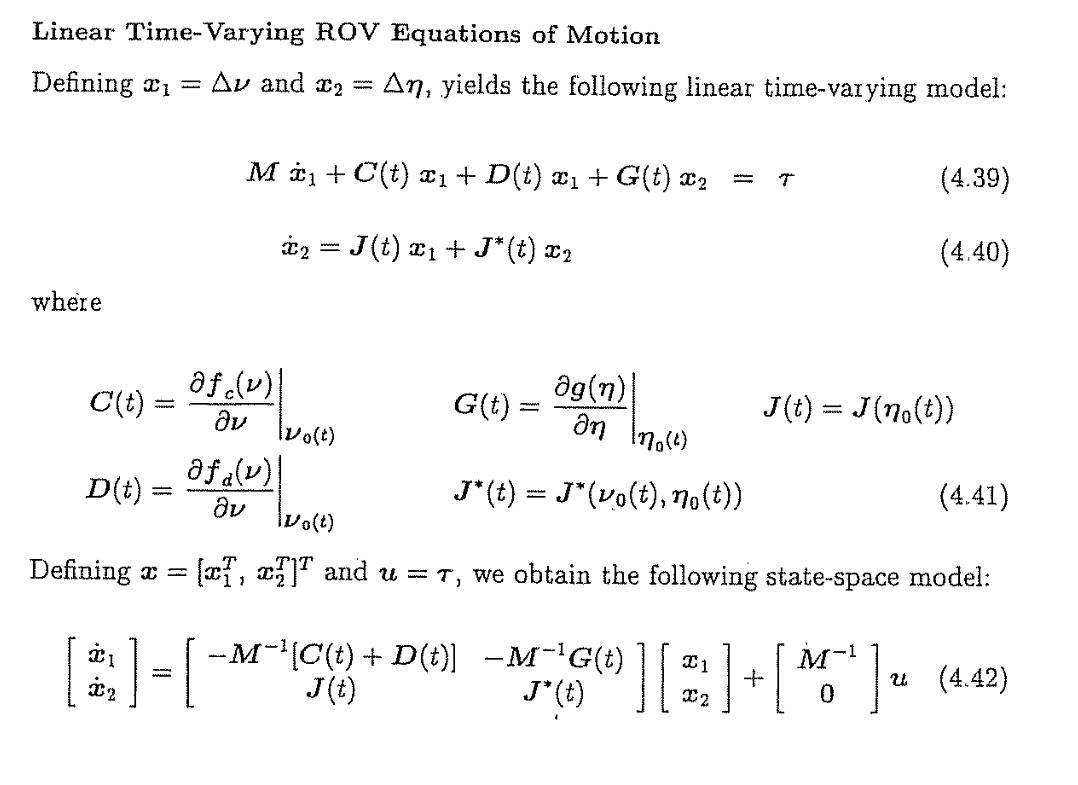

    % calcules des jacobiennes
    Dj = jacobian(D*V,V)

$$Dj = \left[\begin{array}{cccccc} {\mathrm{CD}}_{\mathrm{L1}}+\frac{{\mathrm{AF}}_{1}\,{\mathrm{CD}}_{\mathrm{Q1}}\,\rho \,\left|u\right|}{2}+\frac{{\mathrm{AF}}_{1}\,{\mathrm{CD}}_{\mathrm{Q1}}\,\rho \,u\,\mathrm{sign}\left(u\right)}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{CD}}_{\mathrm{L2}}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q2}}\,\rho \,\left|v\right|}{2}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q2}}\,\rho \,v\,\mathrm{sign}\left(v\right)}{2} & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{CD}}_{\mathrm{L3}}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q3}}\,\rho \,\left|w\right|}{2}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q3}}\,\rho \,w\,\mathrm{sign}\left(w\right)}{2} & 0 & 0 & 0\\ 0 & 0 & 0 & {\mathrm{CD}}_{\mathrm{L4}}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q4}}\,\rho \,\left|p\right|}{2}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q4}}\,p\,\rho \,\mathrm{sign}\left(p\right)}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & {\mathrm{CD}}_{\mathrm{L5}}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q5}}\,\rho \,\left|q\right|}{2}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q5}}\,q\,\rho \,\mathrm{sign}\left(q\right)}{2} & 0\\ 0 & 0 & 0 & 0 & 0 & {\mathrm{CD}}_{\mathrm{L6}}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q6}}\,\rho \,\left|r\right|}{2}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q6}}\,r\,\rho \,\mathrm{sign}\left(r\right)}{2} \end{array}\right]$$

    Cj = jacobian(C*V,V)

    Gj = jacobian(Ge,Ne)

    
    sim(1:7)=J*V;
    sim(8:13)=-(M\Ge) - (M\(C*V + D*V)) + (M\(Tm*U));
  
    Ac = [zeros(7, 7),J;
         -(M\ Gj),-(M\(Cj + Dj))];
    
    Bc = [zeros(7,8);M\Tm];
    
    Cc = jacobian([Ne;V],[Ne;V]);
    
    Dc = jacobian([Ne;V], U );

    
   
    Atest=jacobian(sim,[Ne;V]);
    
% statefontion(1:6) = inv(M) * Fm;
% statefonction(7:13) = J * V;
% 
% A = jacobian(statefonction, [V; Ne])

## Implémentation 

### Substituer les constantes du modèle du sous-marin

%% Chargement des paramètres
    cf = ConfigAUV8();

    constValues = [cf.d14 ...
                 cf.d58 ...
                 cf.a14 ...
                 cf.dz ...
                 cf.z ...
                 cf.mass ...
                 cf.volume ...
                 cf.height...
                 cf.AF ...
                 cf.I(1,:) ...
                 cf.I(2,:) ...
                 cf.I(3,:) ...
                 cf.RG ...
                 cf.RB ...
                 cf.CDL...
                 cf.CDQ...
                 cf.rho ...
                 cf.g];

    
    sim=subs(sim, constMec, constValues);
    
    Av=subs(Ac, constMec, constValues);
    AvTest=subs(Atest, constMec, constValues);
    Bv=subs(Bc, constMec, constValues);


### Linéariser au condition initials.

    % États initaux
    N0=[0;0;.2246;1;0;0;0]

N0 =          0
         0
    0.2246
    1.0000
         0
         0
         0


    V0=[0;0;0;0;0;0]

V0 =      0
     0
     0
     0
     0
     0


    
    A0=double(subs(Av, [Ne;V], [N0;V0]))

A0 =          0         0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    0.5000         0         0
         0         0         0         0         0         0         0         0         0         0         0    0.5000         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.5000
         0         0    0.0072         0   -0.0010    0.6246         0   -1.33

    A0test=double(subs(AvTest, [Ne;V], [N0;V0]))

A0test =          0         0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    0.5000         0         0
         0         0         0         0         0         0         0         0         0         0         0    0.5000         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.5000
         0         0    0.0072         0   -0.0010    0.6246         0   -

    B0=double(Bv);

## Étude

    c0=ctrb(A0,B0);
    nc=rank(c0)

nc = 12

### Générer les fonctions matlab

 matlabFunction(transpose(sim),'File','AUVFossenSimFcn',...
       'Vars',{[Ne;V],U});

## Sous-fonctions personalisées

Ici ce trouve nos fonctions personalisées

### Matrice antisymétrique

function sm=skew(u) 
% Convertie un vecteur 3x1 en une matrice antisymétrique 3x3
    sm=[0,-u(3),u(2);
        u(3), 0, -u(1);
       -u(2), u(1), 0];
end

### Conversion d'une équation non linéaire en matrice

https://stackoverflow.com/a/42334647

function [A,b] = NlEquationsToMatrix( eq, x )
    %FACTORMAT equationsToMatrix for nonlinear equations
    %   factors out the vector x from eq such that eq = Ax + b
    %   eq does not need to be linear in x
    %   eq must be a vector of equations, and x must be a vector of symbols
    assert(isa(eq,'sym'), 'Equations must be symbolic')
    assert(isa(x,'sym'), 'Vector x must be symbolic')
    n = numel(eq);
    m = numel(x);
    A = repmat(sym(0),n,m);
    for i = 1:n % loop through equations
        [c,p] = coeffs(eq(i),x); % coefficients, powers of x(1)...x(n)
        for j = 1:m % loop through x(1)...x(n)
            for k = 1:numel(p) % loop through found powers/coefficients
                if has(p(k),x(j)) % if power has the j'th variable
                    A(i,j) = A(i,j) + p(k)*c(k)/x(j); % add the coefficient
                end
            end
        end
    end
    b = simplify(eq - A*x,'ignoreanalyticconstraints',true);
end  
   